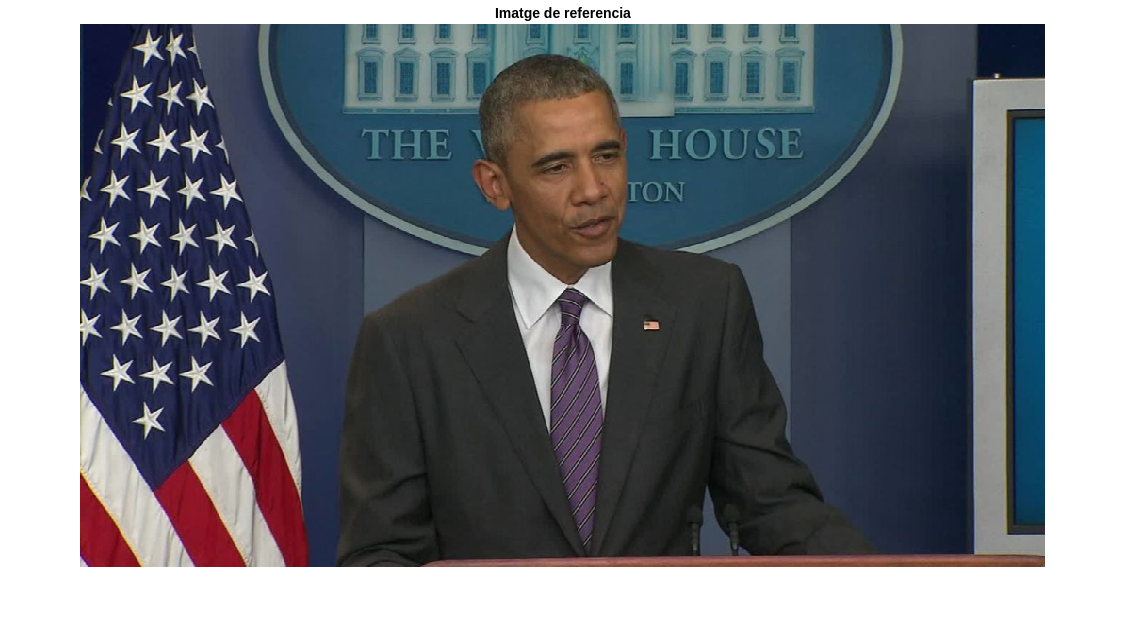

% Detectar elements anatomics de la cara:

% Inicialitzar detector de cares
Detector = vision.CascadeObjectDetector('FrontalFaceLBP');
videoReader = VideoReader('../data/Obama.webm');             % MODIFICAR nom del video


cara_original_video = false;  % MODIFICAR segons si volem  video (true) o imatge (false)


if cara_original_video  % llegir video 
    % llegir primer frame 
    videoFrame = readFrame(videoReader);
    imshow(videoFrame); title("Frame de referencia");
    bbox = step(Detector, videoFrame);
    bbox = bbox(size(bbox,1),:);  % seleccionar la bb mes gran trobada

    selectedFace_f1 = imcrop(videoFrame, bbox);  % retallar nomes la part detectada de la cara

else  % llegir imatge

    image_reference = imread('../data/obama_face3.jpg');            % MODIFICAR imatge de referencia
    imshow(image_reference); title("Imatge de referencia");
    
    bbox2 = step(Detector, image_reference);
    bbox2 = bbox2(size(bbox2,1),:);  % seleccionar la mes gran trobada

    selectedFace_f1 = imcrop(image_reference, bbox2);  % retallar nomes la part detectada de la cara
end

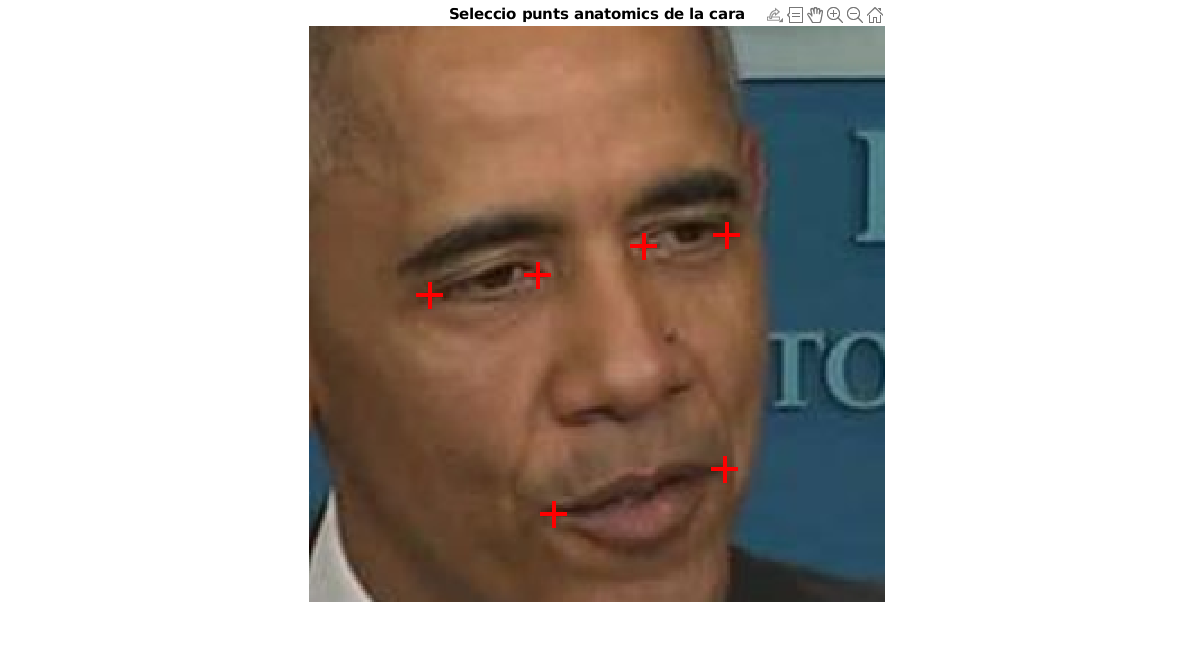

% Reescalar  (sempre imatge 256x256)
selectedFace_f1 = imresize(selectedFace_f1, [256,256]);
imshow(selectedFace_f1); title("Seleccio punts anatomics de la cara")

hold on;
[x, y] = getpts;  % guardar punts marcats
x = round(x); y = round(y);

% mostrar creus vermelles als punts
plot(x, y, 'r+', 'MarkerSize', 20, 'LineWidth', 3, 'Color','red');

hold off;

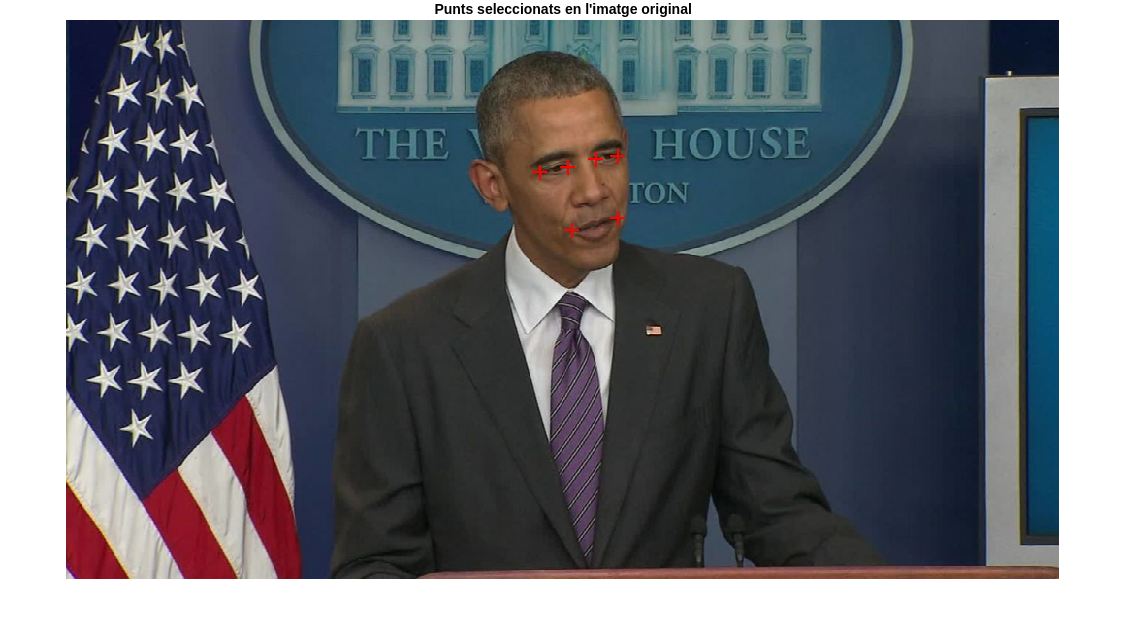

% Dibuixar punts al frame o imatge original

if cara_original_video
    % Mapejar els punts seleccionats en les coordenades originals
    x_orig = (x - 1) * bbox(3) / 256 + bbox(1);
    y_orig = (y - 1) * bbox(4) / 256 + bbox(2);
    imshow(videoFrame); title("Punts seleccionats en el frame original");

    hold on;
    plot(x_orig, y_orig, 'r+', 'MarkerSize', 11, 'LineWidth', 2);
    hold off;

    % Vector de caracteristiques dels punts anatomics
     % Calcul dels features en una funcio, a partir dels punts marcats i la cara actual
    feature_vector = calculate_features(x, y, selectedFace_f1); 

else   % tenim imatge de referencia
    % Mapejar els punts seleccionats en les coordenades originals de l'imatge
    x_orig = (x - 1) * bbox2(3) / 256 + bbox2(1);
    y_orig = (y - 1) * bbox2(4) / 256 + bbox2(2);
    imshow(image_reference); title("Punts seleccionats en l'imatge original");

    hold on;
    plot(x_orig, y_orig, 'r+', 'MarkerSize', 11, 'LineWidth', 2);
    hold off;
end

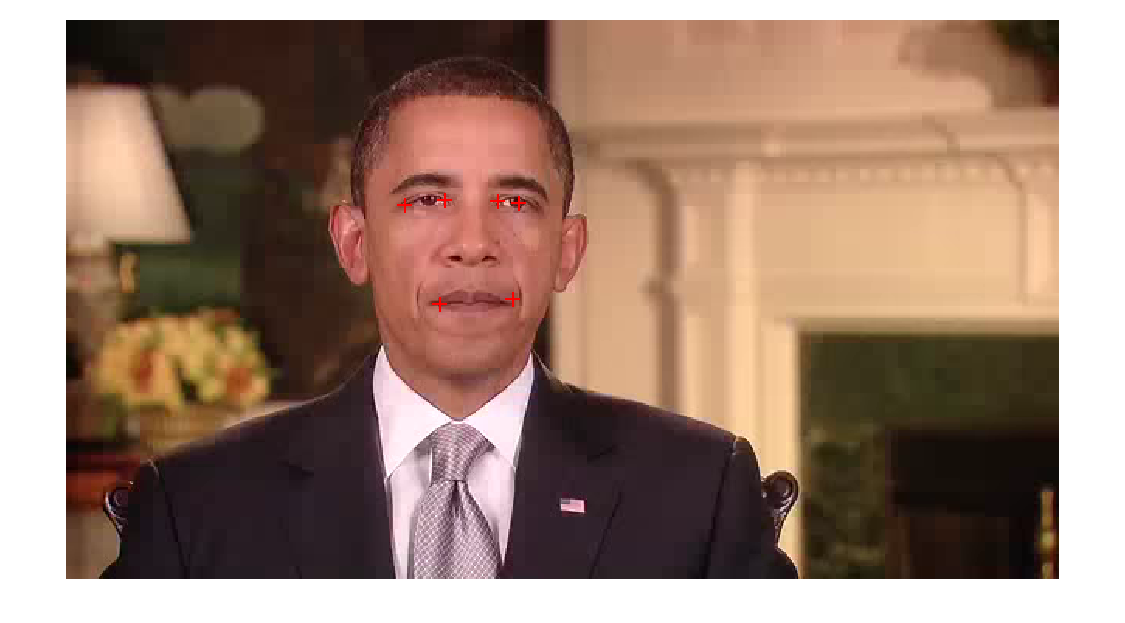

% NOMES EXECUTAR seccio si tenim imatge de referencia, sino no cal

% continuacio de la part anterior si hi havia imatge de referencia
if not(cara_original_video)
    % Fer matching a la cara del primer frame del video
    videoFrame = readFrame(videoReader);

    bbox = step(Detector, videoFrame);
    bbox = bbox(size(bbox,1),:);  % seleccionar la mes gran trobada

    selectedFace_ini = imcrop(videoFrame, bbox);  % retallar nomes la part detectada de la cara
    
    % Reescalar imatge cara
    selectedFace_ini = imresize(selectedFace_ini, [256,256]);
   
    % Buscar matching de punts segons els features 
  
    finestra_busqueda = 15;  % finestra a mirar al voltant dels punts seleccionats, per optimitzar la cerca
   
    % Vector de caracteristiques dels punts anatomics de la imatge de
     % referencia amb els punts seleccionats
    feature_vector = calculate_features(x, y, selectedFace_f1);   


    % Coordenades on hi haura els punt del pixel amb similitud maxima als features
    [x_max, y_max] = calculate_match(finestra_busqueda, selectedFace_ini, x, y, feature_vector);
    
    % dibuixar punts al frame original
    
    % Mapejar els punts seleccionats en les coordenades originals
    x_orig = (x_max - 1) * bbox(3) / 256 + bbox(1);
    y_orig = (y_max - 1) * bbox(4) / 256 + bbox(2);
    
    imshow(videoFrame);
    
    hold on;
    plot(x_orig, y_orig, 'r+', 'MarkerSize', 11, 'LineWidth', 2);
    hold off;
    
    % actualitzar punts pel seguent frame
    x = x_max;
    y = y_max;
    
    % tornar a calcular vector features, pero ara sobre el primer frame ja
    % detectat els punts on toquen
    feature_vector = calculate_features(x, y, selectedFace_ini);  

end

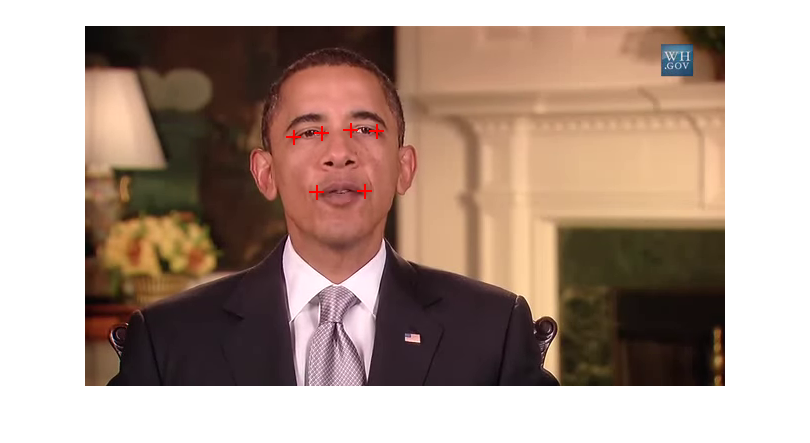

% Tracking en el video

while hasFrame(videoReader)
    videoFrame = readFrame(videoReader);
    bbox = step(Detector, videoFrame);    

    if isempty(bbox)
        continue; % saltar el frame si no detecta cap cara
    end
   
  
    bbox_converted = bbox(size(bbox,1),:);  % quedarse amb el bounding box mes gran detectat

    % Seleccionar cara:
    selectedFace_f2 = imcrop(videoFrame, bbox_converted);
    
    % Reescalar imatge cara
    selectedFace_f2 = imresize(selectedFace_f2, [256,256]);
    % Buscar matching de punts segons els features 
    
    finestra_busqueda = 5;  % finestra a mirar al voltant dels punts seleccionats, per optimitzar la cerca
    
    % Coordenades on hi haura els punt del pixel amb similitud maxima als features
    [x_max, y_max] = calculate_match(finestra_busqueda, selectedFace_f2, x, y, feature_vector);
    
    % dibuixar punts al frame original
    
    % Mapejar els punts seleccionats en les coordenades originals
    x_orig = (x - 1) * bbox(3) / 256 + bbox(1);
    y_orig = (y - 1) * bbox(4) / 256 + bbox(2);
    
    imshow(videoFrame);
    
    hold on;
    plot(x_orig, y_orig, 'r+', 'MarkerSize', 11, 'LineWidth', 2);
    hold off;
    pause(0.00005); % petita pausa per veure el frame actual del video
    
    % actualitzar punts per el seguent frame
    x = x_max;
    y = y_max;
end